close all 
%Range of Motion Rehab CONTROLS PROJECT 
%Adam Chung 
%03/26/2021

%INIT
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
robot = importrobot("ROM_bot.urdf") %Create rigidBodyTree obj

robot =   rigidBodyTree with properties:

     NumBodies: 3
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'lever_arm'  'linear_arm'  'handle'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


ans =    450     1


ans =    450   450


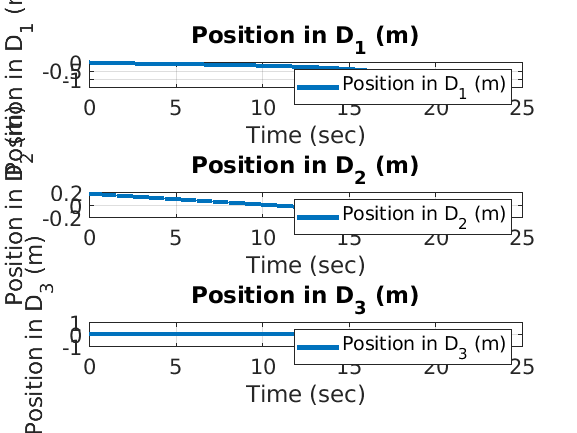

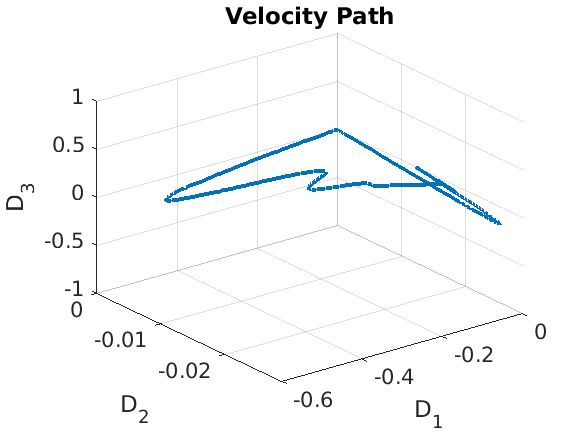

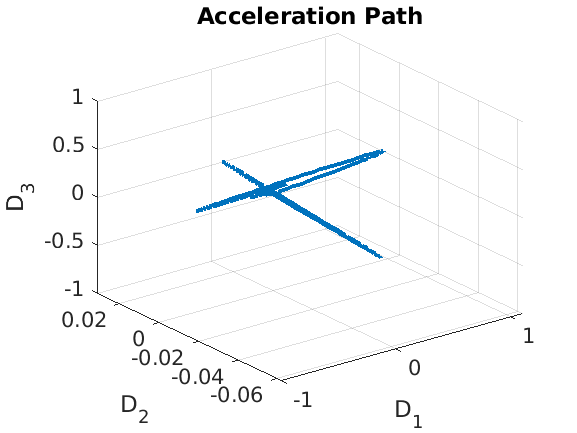

robot.Gravity = [0 0 -9.81]; 
iviz = interactiveRigidBodyTree(robot,"MarkerBodyName","handle"); %Sim enviroment
ax = gca;
plane = collisionBox(0,0,0.025); %Floor init
plane.Pose = trvec2tform([0.25 0 -0.055]); %Floor pose
show(plane,'Parent', ax);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Define Trajectory and Input Parameters 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Define desired Average Velocity and curve type depending on length of
%fingers, going to implement ROM input soon 
ROM = pi/2;
vel = 0.07;
reps = 10;
%Store generated trajectory in workspace for Simulink


[q_deisred,qd_desired,qdd_desired] = mjtTrajectoryGeneration(ROM,vel,reps); 



%Simulate desired trajectories with controllers and choose which one to show
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
simout_CPM = sim('CPM.slx');

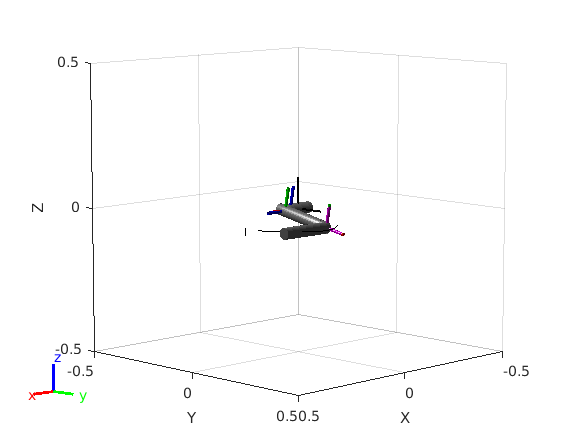

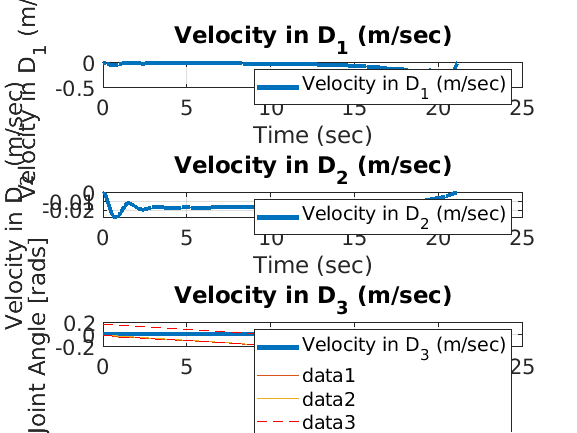

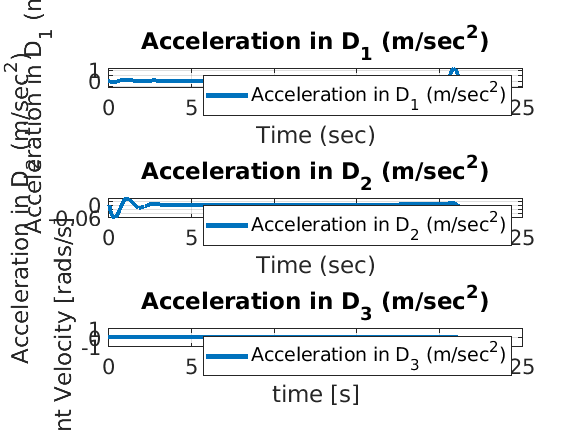

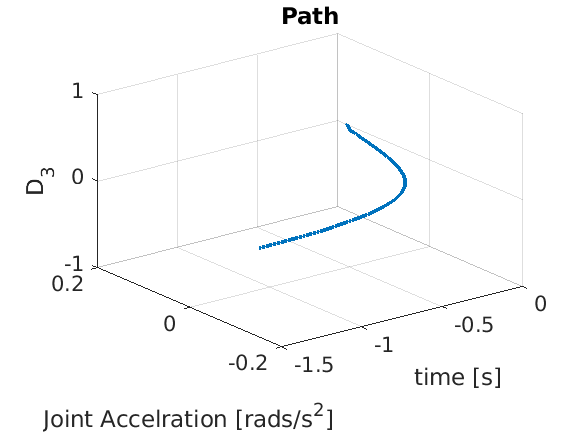


qdot_desired =

     []



%simout_PD = sim('PD.slx'); 

%controller = 1 ==> Computed Torque Control
%controller = 2 ==> PD Control 

controller = 1; 
switch controller 
    case 1 
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_CPM.tout)/(max(simout_CPM.tout)));
        for i = 1:length(simout_CPM.tout)
            iviz.Configuration = simout_CPM.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end
        
        q = simout_CPM.q_cpm; 
        q_desired = simout_CPM.q_desired; 
        
        qdot = simout_CPM.qdot_cpm; 
        qdot_desired = simout_CPM.qdot_desired
        
        qddot = simout_CPM.qddot_cpm; 
        qddot_desired = simout_CPM.qddot_desired; 
        
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        ylabel("Joint Angle [rads]")
        xlabel("time [s]")
        hold off
        
        figure(4) 
        hold on
        plot(qdot)
        plot(qdot_desired,'--r')
        ylabel("Joint Velocity [rads/s]")
        xlabel("time [s]")
        hold off 
        
        figure(5)
        hold on 
        plot(qddot)
        plot(qddot_desired,'--r')
        ylabel("Joint Accelration [rads/s^2]")
        xlabel("time [s]")
        hold off
    case 2
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_PD.tout)/(max(simout_PD.tout)));
        for i = 1:length(simout_PD.tout)
            iviz.Configuration = simout_PD.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end  
        q = simout_PD.q_pd; 
        q_desired = simout_PD.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%